Set up datastore

datapath = [pwd filesep 'data' filesep 'Data' filesep 'Stocks']

datapath = '/home/christoph/MatlabProjects/PricePrediction/data/Data/Stocks'

ds = datastore(datapath)

ds =   TabularTextDatastore with properties:

                      Files: {
                             ' .../christoph/MatlabProjects/PricePrediction/data/Data/Stocks/a.us.txt';
                             ' .../christoph/MatlabProjects/PricePrediction/data/Data/Stocks/aa.us.txt';
                             ' .../christoph/MatlabProjects/PricePrediction/data/Data/Stocks/aaap.us.txt'
                              ... and 7192 more
                             }
                    Folders: {
                             '/home/christoph/MatlabProjects/PricePrediction/data/Data/Stocks'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
      PreserveVariableNames: false
          ReadVariableNames: true
              VariableNames: {'Date', 'Open', 'High' ... and 4 more}
             DatetimeLocale: en_US

  Text Format Properties:
      

[data,info] = read(ds)

data = 4521×7 table
       Date        Open      High      Low      Close       Volume      OpenInt
    __________    ______    ______    ______    ______    __________    _______

    1999-11-18    30.713    33.754    27.002    29.702    6.6278e+07       0   
    1999-11-19    28.986    29.027    26.872    27.257    1.6143e+07       0   
    1999-11-22    27.886    29.702    27.044    29.702    6.9703e+06       0   
    1999-11-23    28.688    29.446    27.002    27.002    6.3321e+06       0   
    1999-11-24    27.083    28.309    27.002    27.717    5.1321e+06       0   
    1999-11-26    27.594    28.012    27.509    27.807    1.8326e+06       0   
    1999-11-29    27.676     28.65     27.38    28.432    4.3178e+06       0   
    1999-11-30     28

info = struct with fields:
             Filename: '/home/christoph/MatlabProjects/PricePrediction/data/Data/Stocks/a.us.txt'
             FileSize: 223899
               Offset: 0
    NumCharactersRead: 223899


data = add_COD(data);
data = add_HLD(data);
data = add_WMA(data,5,'Close',0.08);
data = add_WMA(data,30,'Close',0.2);

n = 200

n = 200

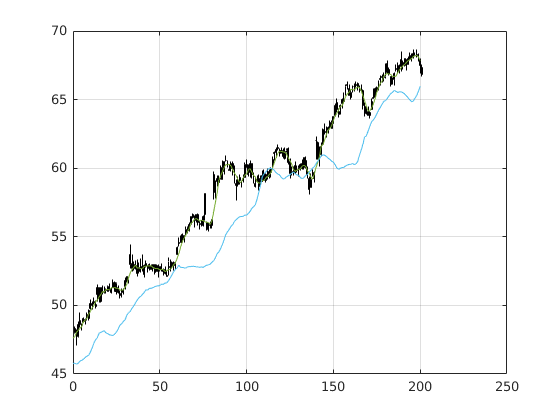

candle(data(end-n:end,:),'k');
hold on;
plot(0:n,data.WMA5_Close(end-n:end));
plot(0:n,data.WMA30_Close(end-n:end));
hold off

Plotting function

function fig = plotStock(data)
    fig = figure;
    
    splot(1) = subplot(211);
    p(1) = plot(data.Date,data.Close);
    splot(1).YScale = 'log';
    
    splot(2) = subplot(212);
    p(2) = plot(data.Date,data.Volume);
    
end

Close-Open difference function

-> adds COD (Close Open Difference) variable to the input table

function tbl = add_COD(tbl)
    COD = tbl.Close-tbl.Open;
    tbl = addvars(tbl,COD);
end

High-Low difference function

-> adds HLD (High Low Difference) variable to the input table

function tbl = add_HLD(tbl)
    HLD = tbl.High-tbl.Low;
    tbl = addvars(tbl,HLD);
end

Weighted Moving Average

function tbl = add_WMA(tbl,windowSize,var,wCoeff)
    try
        var = string(var);
    catch ME
        warning("WMA - Changing 'var' to data type String failed.")
    end

    %Check if variable exists
    varExists = var==tbl.Properties.VariableNames;
    varExists = nnz(varExists);
    if ~varExists
        warning("WMA - Variable to be move-averaged doesn't exist");
    end

    %Create weights - higher wCoeff => higher weight on right-side window
    %values
    weights = exp(wCoeff*(1:windowSize));
    weights = weights ./ sum(weights);
        
    WMA = movavg(tbl.(var),'custom',weights);
    stringWMA = strcat("WMA",string(windowSize),"_",string(var));
    tbl = addvars(tbl,WMA,'NewVariableNames',stringWMA);
        
end